# Module 7: Application of MATLAB in Numerical Analysis I -- Randomness

## 1. Random Numbers in MATLAB

In fact, the random numbers in MATLAB are ***pseudo-random****, *they are generated from [random number stream ](https://www.mathworks.com/help/matlab/ref/randstream.html)-- a series of numbers calculated by deterministic algorithms (e.g. numer theory). 

In principle, the random numbers in MATLAB do not satisfy the rigorous **independent and identically distributed** (i.i.d.) condition in probability theory. However, they can pass statistical tests on their distribution and correlation to show that they are good approximations -- that's typically sufficient for application purpose.

rand % random number from uniform distribution (continuous)

ans = 0.9379

randn % random number from normal distribution

ans = 0.1654

randi([0 10])

ans = 2

## 2. Calculating $\pi$ with [Monte-Carlo Method](https://en.wikipedia.org/wiki/Monte_Carlo_method#History)

Monte Carlo Method -- a numerical technique (used in mathematics and engineering) to estimate complex quantities or solve problems that are difficult to analyze analytically. 

It relies on randomness and probability to simulate a large number of random trials, allowing us to approximate solutions or calculate probabilities. 

One of its applications is to approximate the value of $\pi$, which takes the following steps (based on Wikipedia):

1. Draw a square, then [inscribe](https://en.wikipedia.org/wiki/Inscribed_figure) a quadrant within it.

2. [Uniformly](https://en.wikipedia.org/wiki/Uniform_distribution_(continuous)) scatter a given number of points over the square.

3. Count the number of points inside the quadrant, i.e. having a distance from the origin of less than 1.

4. The ratio of the inside-count and the total-sample-count is an estimate of the ratio of the two areas, $\frac{\pi }{4}$. Multiply the result by 4 to estimate $\pi$.

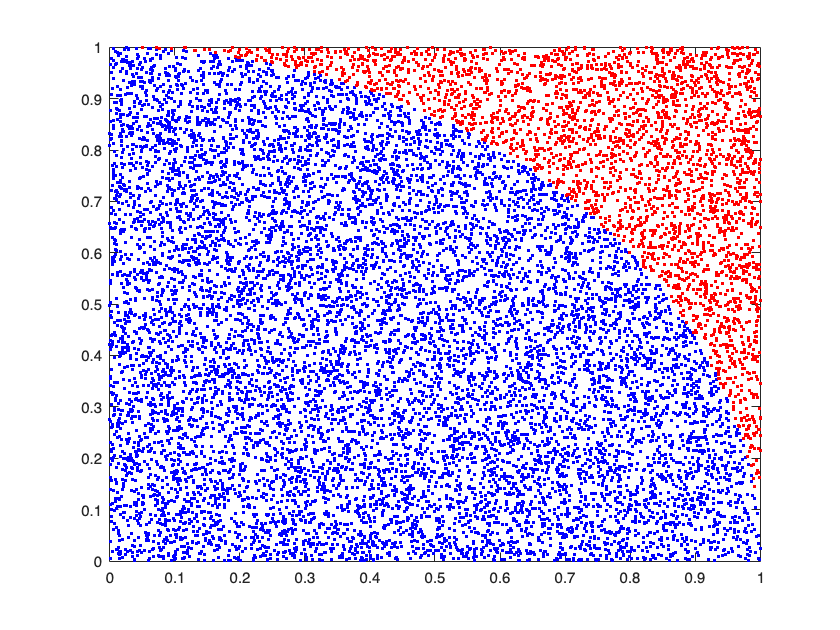

N = 14000; % total number of random points

x = rand(N,1); % the x-coordinate of the random points
y = rand(N,1); % the y-coordinate of the random points

r = x.^2+y.^2; % the distance to the orgin

% get logicals 
inside = r<=1 ; % index of the points that are inside the quadrant
outside = r>1 ; % or simply outside = ~inside

% plot 
plot(x(inside),y(inside),'b.');
hold on  % continue plot within the same figure
plot(x(outside),y(outside),'r.');
hold off % stop the hold, creating new figure if N is changed

pi_est = 4*sum(inside)/N;  % get the estimated pi value
err = pi_est - pi % compare it with MATLAB-saved pi

err = -0.0064

### ***In-class Exercise 1*** 

Use the for-loop and if statements to implement the same algorithm

N =3000; % total number of random points
inside = 0;

for i=1:N
    x = rand();
    y = rand();
    if x^2+y^2<=1
        inside = inside + 1;
    end 
end

inside = 4*inside; % circle iteration
pi_est = inside/N  % total iterations

pi_est = 3.1240

err = pi_est - pi % compare it with MATLAB-saved pi

err = -0.0176

## 3. Simulation of [Random Walk](https://en.wikipedia.org/wiki/Random_walk#cite_note-6)

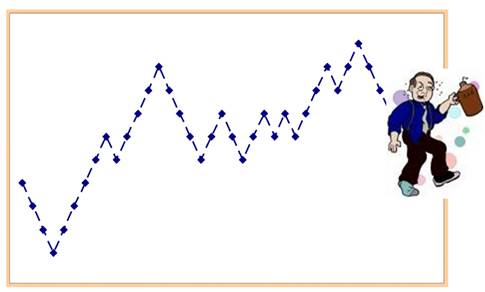

In each unit time (time period), going from left to right, the value of the variable takes an independent random step up or down, a so-called **random walk**.

(source: [https://people.duke.edu/~rnau/411rand.htm](https://people.duke.edu/~rnau/411rand.htm) )

If we ignore the "left to right" movement, only consider "random steo up or down", and "rotate it 90 degrees", we can view such process on the x-axis:

(50% probability for either direction -- *simple random walk*)

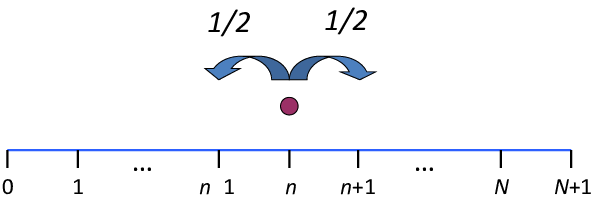

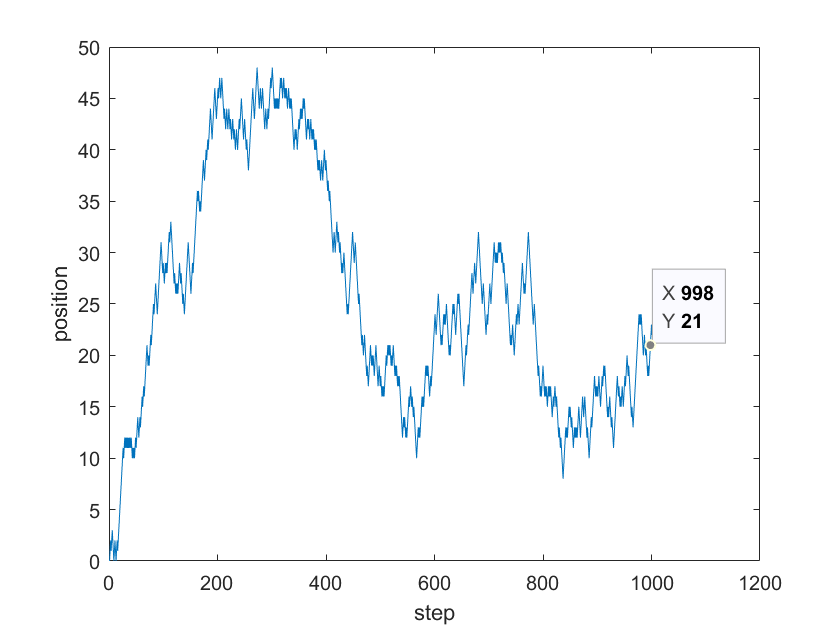

n = 1000;
v = random_walk(n);
plot(v)
xlabel('step')
ylabel('position')

Where is the random walker after n steps? It is a random number, but we can see its distribution with the histogram by simulating the random walk for N times.

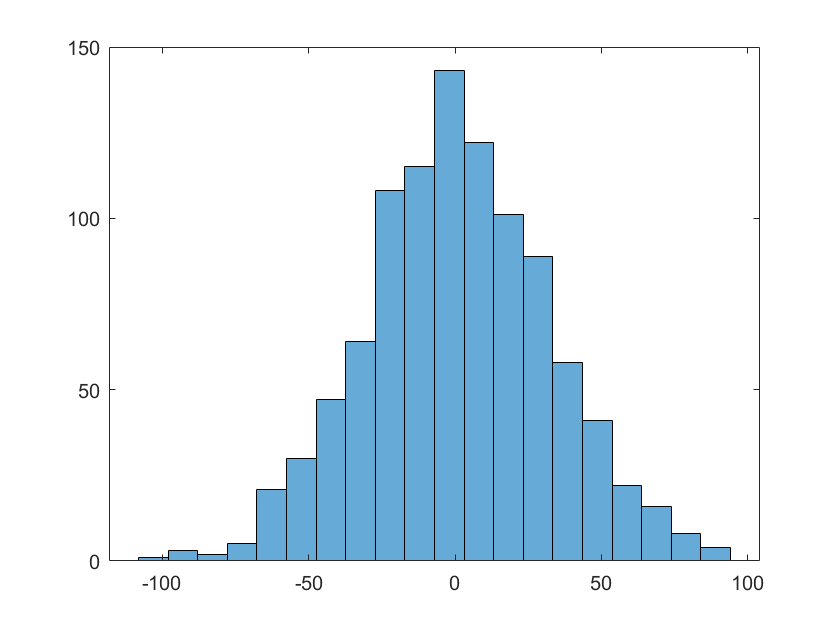

N = 1000;
n = 1000;
pos_end = zeros(1,N);

for i = 1:N
    v = random_walk(n);
    pos_end(i) = v(end);
end

histogram(pos_end, 20) % the second value represent number of bins in histogram

Want to learn more about the `histogram` function? Check out its help page [here](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram.html?s_tid=doc_ta)!

### ***In-class Exercise 2*** 

On average, how far will the random walker travel after n steps (i.e. the absolute value of the position after n steps)? Write the function `aver_dist(n,N)` to approximate this with N simulations.

N = 1000; % number of simulations
n = 1000; % number of steps

aver_dist(n,N)

ans = 24.7940

***Example 1: In mathematical ecology, random walks are used to describe individual animal movements, to model population dynamics.***

***(the moving direction & moving stepsize can rely on different factors such as food and temperature.)***

***Example 2: several online random walk simulators:***

[http://e.sci.osaka-cu.ac.jp/yoshino/download/rw/](http://e.sci.osaka-cu.ac.jp/yoshino/download/rw/) 

[https://demonstrations.wolfram.com/SimulatingTheSimpleRandomWalk/](https://demonstrations.wolfram.com/SimulatingTheSimpleRandomWalk/) 

## 4. Other useful links

**Christopher Davis**’s videos about MATLAB: [https://www.youtube.com/playlist?list=PLHfGN68wSbbLjreDKYLZw8Mq8iw8cIPAH](https://www.youtube.com/playlist?list=PLHfGN68wSbbLjreDKYLZw8Mq8iw8cIPAH)

**Yasmeen Baki**’s videos about MATLAB: [https://www.youtube.com/playlist?list=PL6ue_xaI6w4OQt5xwMvhjhaXSjuL0xbym](https://www.youtube.com/playlist?list=PL6ue_xaI6w4OQt5xwMvhjhaXSjuL0xbym) 

## 5. **Functions defined in this livescript**

function v = random_walk(n)
% random walk of n steps
% output the vector of length (n+1)
% the first value is the initial position zero
    v = zeros(1,n+1); % first value stores the initial position
    for i = 2:n+1
        v(i) = v(i-1)+(-1)^randi(2);
    end
end

function d = aver_dist(n,N) % In-class Exercise 2

pos_end = zeros(1,N);
total_dis = 0;

    for i = 1:N
        v = random_walk(n);
        pos_end(i) = v(end);
        total_dis = total_dis + abs(v(end));
    end
d = total_dis/N;

end